# 第5章 数字滤波器结构

## 5.8 有限长单位脉冲响应数字滤波器设计

### 5.8.2 线性相位FIR数字滤波器的特点

#### `Ch5_8_3`

线性相位FIR数字滤波器的特点

实现情况3

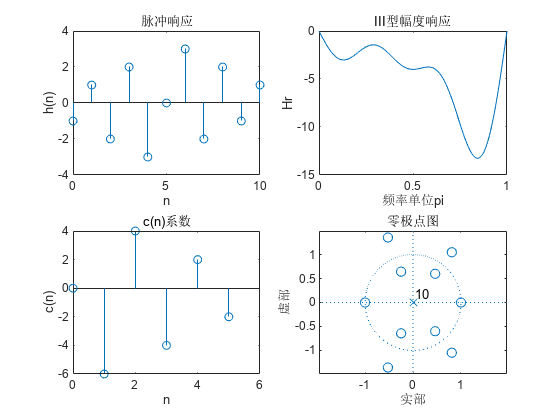

h = [-1 1 -2 2 -3 0 3 -2 2 -1 1];
M = length(h);
n = 0:M-1;
[Hr,w,c,L] = hr_type3(h);
subplot(2,2,1); stem(n,h); 
xlabel('n'); ylabel('h(n)'); title('脉冲响应')
subplot(2,2,2); plot(w/pi,Hr); 
xlabel('频率单位pi'); ylabel('Hr'); title('III型幅度响应')
subplot(2,2,3); stem(0:L,c); 
xlabel('n'); ylabel('c(n)'); title('c(n)系数')
subplot(2,2,4); zplane(h,1); title('零极点图')